main

animateOn = true; 
speedupfactor = 12; % animation speed up 
z_robot = 0.78;
stateC = [0, 0, z_robot];
robot = createRobot(stateC, z_robot);

--------------------
Robot: (18 bodies)

 Idx        Body Name       Joint Name       Joint Type        Parent Name(Idx)   Children Name(s)
 ---        ---------       ----------       ----------        ----------------   ----------------
   1        rightleg1        rightjnt1        prismatic                 base(0)   rightleg2(2)  
   2        rightleg2        rightjnt2        prismatic            rightleg1(1)   rightleg3(3)  
   3        rightleg3        rightjnt3         revolute            rightleg2(2)   rightleg4(4)  
   4        rightleg4        rightjnt4         revolute            rightleg3(3)   rightleg5(5)  
   5        rightleg5        rightjnt5         revolute            rightleg4(4)   rightleg6(6)  
   6        rightleg6        rightjnt6         revolute            rightleg5(5)   rightleg7(7)  
   7        rightleg7        rightjnt7         revolute            rightleg6(6)   rightleg8(8)  
   8        rightleg8        rightjnt8         revolute            rightleg7(7)   

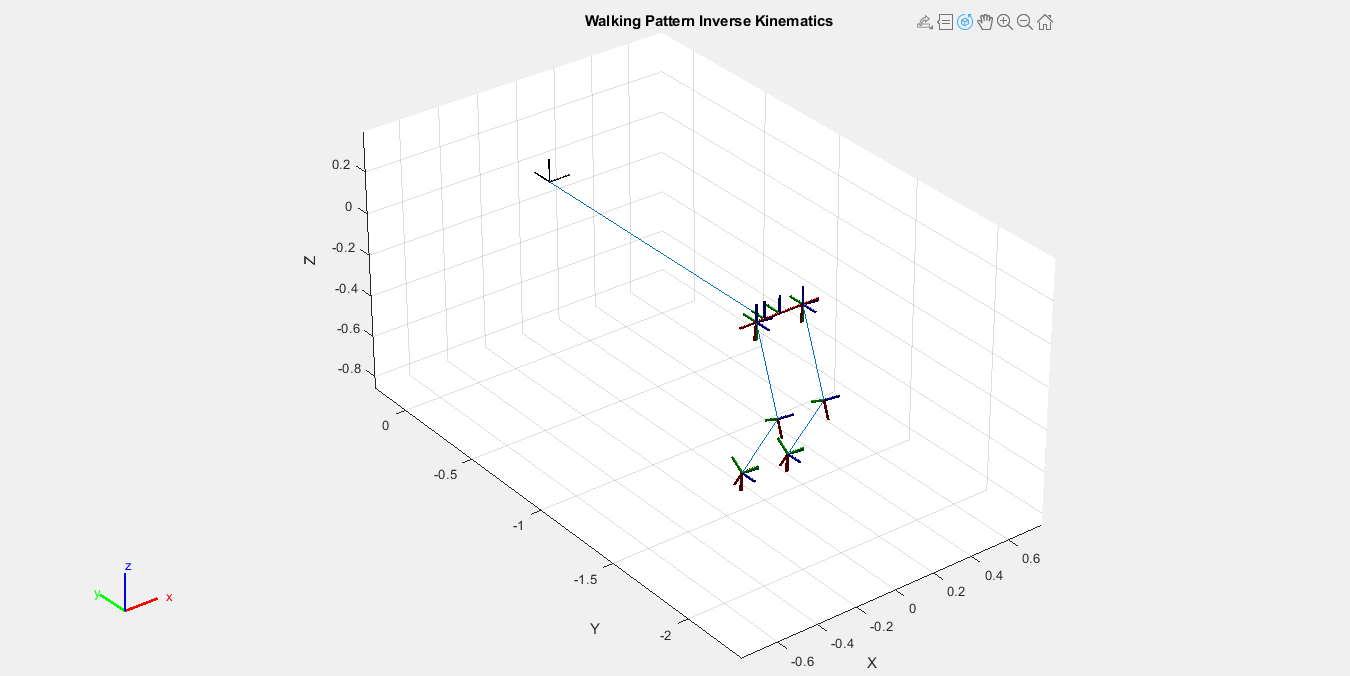

for sIdx = 1:length(footinfos)
    % Extract X Y Z position states (indices 1, 3, and 5)
    stateL = footinfos{sIdx}.footleft([3 1 5],:); 
    stateR = footinfos{sIdx}.footright([3 1 5],:); 
    stateCoM = footinfos{sIdx}.state([3 1 5],:);
    % Initialize matrices
    numIdx = size(stateL,2); 
    jointsLeft = zeros(6,numIdx); 
    jointsRight = zeros(6,numIdx); 
    transMatLeft = zeros(4,4,numIdx); 
    transMatRight = zeros(4,4,numIdx); 
   
    % Skip some intermediate steps when visualizing 
    for idx = 1:numIdx
        [qLeft, transmatL, qRight,transmatR] = animate(stateR(:,idx), stateL(:,idx), stateCoM(:,idx), animateOn, robot, speedupfactor, idx);
        jointsLeft(:,idx) = qLeft; 
        transMatLeft(:,:,idx) = transmatL;
        jointsRight(:,idx) = qRight; 
        transMatRight(:,:,idx) = transmatR; 
        % save joints info 
        footinfos{sIdx}.jointsleft = jointsLeft; 
        footinfos{sIdx}.jointsright = jointsRight; 
        footinfos{sIdx}.transmatleft = transMatLeft; 
        footinfos{sIdx}.transmatright = transMatRight; 
    end
end

#### `updateJoints function`

function updateJoints(robot, anglesright, anglesleft, stateC)
    desconfig = robot.homeConfiguration;
    
    desconfig(1).JointPosition = stateC(2); % angle offset
    desconfig(2).JointPosition = stateC(1);
    for idx = 1:length(anglesright)
        desconfig(idx+3).JointPosition = anglesright(idx);
    end 
    desconfig(4).JointPosition = desconfig(4).JointPosition - pi;
    desconfig(5).JointPosition = desconfig(5).JointPosition + pi/2; 
    
    desconfig(10).JointPosition = stateC(2);
    desconfig(11).JointPosition = stateC(1);
    for idx = 1:length(anglesleft)
        desconfig(idx+12).JointPosition = anglesleft(idx);
    end 
    desconfig(13).JointPosition = desconfig(13).JointPosition - pi; 
    desconfig(14).JointPosition = desconfig(14).JointPosition + pi/2; 
       
    % update graphics 
    show(robot, desconfig, 'PreservePlot', false);
    title('Walking Pattern Inverse Kinematics')
    pause(0.001)
end

`createRobot function`

function robot = createRobot(stateC, z_robot)

% NOTE: make sure parameters match in inverse kinematics function 
L1 = 0.12; 
L2 = 0; 
L3 = 0.4;
L4 = 0.38;
L5 = 0;
       
robot = rigidBodyTree;
% Right Leg
dhparams = [0       0        0      0;     % Base -> pelvisy
            0       0        0      0;     % pelvisy -> pelvisx
            L1      0       -L2     0;     % pelvisx -> hip yaw
            0      -pi/2     0      0;     % Hip yaw -> hip roll
            0      -pi/2     0      0;     % Hip roll -> hip pitch       
            L3      0        0      0;     % Hip pitch -> knee pitch
            L4      0        0      0;     % Knee pitch -> ankle pitch
            0       pi/2     0      0;     % Ankle pitch -> ankle roll
            L5      0        0      0];    % Ankle roll -> end effector (foot)
       
for idx = 1:size(dhparams,1)
    rightLeg(idx) = rigidBody("rightleg"+idx);
    rightJnt(idx) = rigidBodyJoint("rightjnt"+idx, 'revolute');
    if idx==1 || idx==2
        rightJnt(idx) = rigidBodyJoint("rightjnt"+idx, 'prismatic');
        if idx==1 
            rightJnt(idx).JointAxis = [0 -1 0];
        else
           rightJnt(idx).JointAxis = [1 0 0];
        end
    end
    setFixedTransform(rightJnt(idx),dhparams(idx,:),'dh'); 
    rightLeg(idx).Joint = rightJnt(idx);
    if idx==1
        addBody(robot,rightLeg(idx),"base");     
    else
        addBody(robot,rightLeg(idx),"rightleg"+(idx-1));
    end
    
end

% Left Leg
dhparams = [0      0         0      0;
            0      0         0      0;
           -L1     0        -L2     0;    % Only difference with right leg is the
            0     -pi/2      0      0;    % first element is -L1 instead of L1
            0     -pi/2      0      0; 
            L3      0        0      0;
            L4      0        0      0;
            0       pi/2     0      0;
            L5      0        0      0];
        
for idx = 1:size(dhparams,1)
    leftLeg(idx) = rigidBody("leftleg"+idx); 
    leftJnt(idx) = rigidBodyJoint("leftjnt"+idx, 'revolute');
    if idx==1 || idx==2
        leftJnt(idx) = rigidBodyJoint("leftjnt"+idx, 'prismatic');
        if idx==1 
            leftJnt(idx).JointAxis = [0 -1 0];
        else
            leftJnt(idx).JointAxis = [1 0 0];
        end
    end
    setFixedTransform(leftJnt(idx),dhparams(idx,:),'dh'); 
    leftLeg(idx).Joint = leftJnt(idx);
    if idx==1
        addBody(robot,leftLeg(idx),"base");     
    else
        addBody(robot,leftLeg(idx),"leftleg"+(idx-1));
    end
end

showdetails(robot)
hFig = figure; 
hFig.Visible = 'on'; 
hFig.Units = 'Normalized'; 
hFig.OuterPosition = [0 0 1 1];
hAx2 = axes(hFig);


desconfig = robot.homeConfiguration;


qright0 = zeros(1,6); 
qleft0 = zeros(1,6);
updateJoints(robot, qright0, qleft0, stateC)
view(3)
grid on
axis([-z_robot z_robot -3*z_robot 0.3*z_robot  -1.1*z_robot 0.5*z_robot])
hold on
end

`animate function`

function [qLeft, transmatL, qRight,transmatR] = animate(stateR, stateL, stateCoM, animateOn, robot, speedupfactor, idx)

n = [0;  0; -1]; % x
s = [-1; 0; 0];  % y
a = [0;  1; 0];  % z
R = [n s a];   

% Get Left joints
p = stateL.*[-1; 1; 1]-stateCoM.*[1; 1; 1];
transmatL =  [R     p; 
            [0 0 0 1]];
isLeft = true; 
qLeft = invKinBody2Foot(transmatL, isLeft); % Call IK function

% Get Right joints
p = stateR.*[-1; 1; 1]-stateCoM.*[1; 1; 1]; 
transmatR =  [R     p; 
            [0 0 0 1]];
isLeft = false; 
qRight = invKinBody2Foot(transmatR, isLeft);

% Animate
if animateOn
    if rem(idx,speedupfactor) == 0
        updateJoints(robot, qRight, qLeft, stateCoM);
    end 
end  
end